%%OPEN LOOP TRANSFER FUNCTIONS
num_armax = [0.7555];
den_armax = [1 13.87 34.91];
transfer_armax = tf( num_armax, den_armax);
%%CLOSED LOOP TREANSFER FUNCTIONS
transfer_armax_closed_loop = feedback( transfer_armax, 1);
[ wn, zeta] = damp(transfer_armax_closed_loop)

wn =     3.4096
   10.4604


zeta =      1
     1


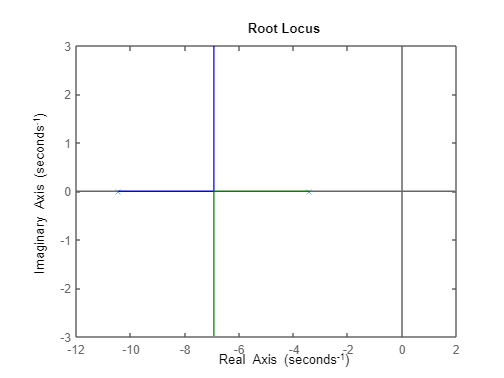

rlocus(transfer_armax_closed_loop);

%%OPEN LOOP TRANSFER FUNCTIONS
num_BJ = [0.6979];
den_BJ = [1 12.23 35.01];
transfer_BJ = tf( num_BJ, den_BJ);
%%CLOSED LOOP TRANSFER FUNCTIONS
transfer_BJ_closed_loop = feedback( transfer_BJ, 1);
[ wn_bj, zeta_bj] = damp(transfer_BJ_closed_loop) 

wn_bj =     4.8168
    7.4132


zeta_bj =      1
     1


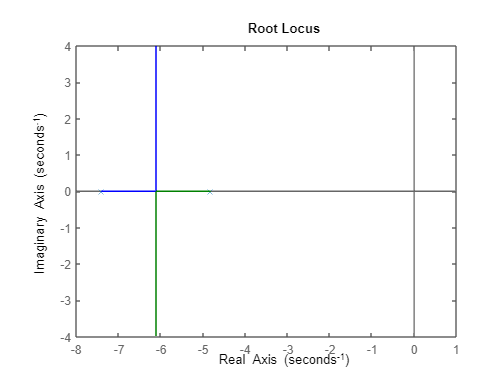

rlocus(transfer_BJ_closed_loop);